sentFile = ["1_Room_noSEPA_sent.dat"
    "2_Room_noSEPA_sent_b.dat"
    "4_Room_txSEPA_sent_b.dat"
    "6_Room_rxSEPA_sent_b.dat"
    ];

sent_cnt = length(sentFile);

recvFile = ["1_Room_noSEPA_recv.dat"
    "2_Room_noSEPA_recv_b.dat"
    "4_Room_txSEPA_recv_b.dat"
    "6_Room_rxSEPA_recv_b.dat"
    ];
    
recv_cnt = length(recvFile);

for cnt = 1:1:sent_cnt
    csvread(recvFile(cnt))
    sent_data(cnt)= {csvread(sentFile(cnt))};
    recv_data(cnt) = {csvread(recvFile(cnt))};
end

ans =      1    37   214
     1    37   214
     1    25   215
     1    29   214
     1    32   215
     1    30   214
     1    31   214
     1    32   214
     1    25   215
     1    34   214


ans =     15    29   215
    15    28   215
    15    36   215
    15    32   215
    15    26   215
    15    36   215
    15    32   214
    15    28   215
    15    32   215
    15    22   215


ans =     15     4   186
    15     4   185
    15     4   183
    15     4   183
    15     4   184
    15     4   184
    15     4   184
    15     4   183
    15     4   186
    15     4   185


ans =     15     7   179
    15    18   180
    15    20   179
    15    18   179
    15    19   179
    15    20   179
    15    18   179
    15    18   179
    15    19   179
    15    10   179



sent_array = cell2mat(sent_data);

recv_array = [];
for cnt = 1:1:recv_cnt
    temp_data =cell2mat(recv_data(cnt));
    temp_data = temp_data(1:757,:);
    recv_array = [recv_array temp_data];
end


nretx = [];
result = [];
delay = [];
diversity = [];
snr= [] ;
rssi = [];

for cnt = 1:1:sent_cnt
    nretx = [nretx sent_array(:,1 + 3*(cnt-1))];
    result = [result sent_array(:,2 + 3*(cnt-1))];
    delay = [delay sent_array(:,3*cnt)];
    
    diversity = [diversity recv_array(:,1 + 3*(cnt -1))];
    snr = [snr recv_array(:,2 + 3*(cnt -1))];
    rssi = [rssi recv_array(:,3*cnt)];
end

result_mean = [];
for cnt = 1:1:sent_cnt
    result_mean = [result_mean mean(result(:,cnt))];
end

result_mean

result_mean =     0.6790    1.0000    1.0000    1.0000


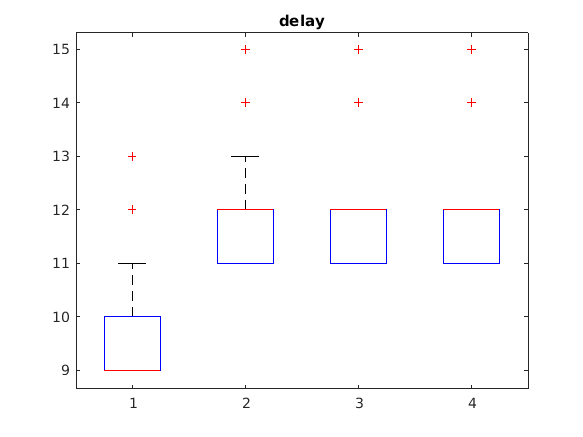



boxplot(delay)
title("delay")

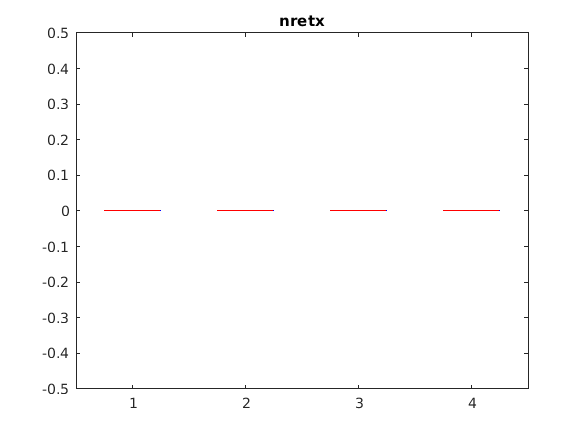

boxplot(nretx)
title("nretx")

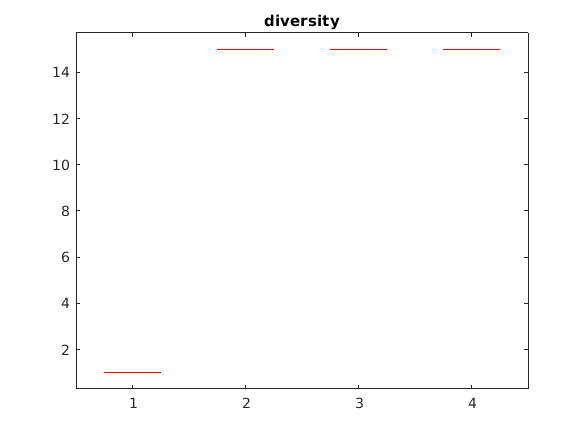

boxplot(diversity)
title("diversity")

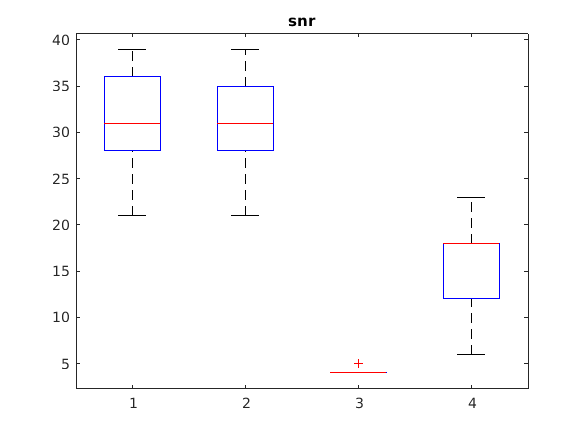

boxplot(snr)
title("snr")

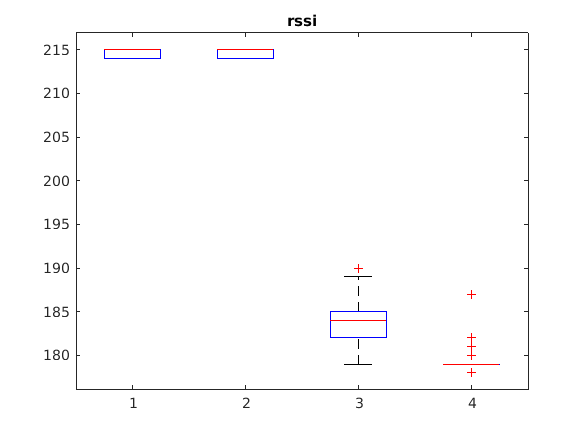

boxplot(rssi)
title("rssi")